# Speech Emotion Recognition based on multi corpus

#                                                                         -------- mixed corpus

clear;              % clear all the workspace
clc;                % clear all the command window
addpath 'D:\Users\Y.H.Tian\Desktop\学习\UOG\Msc Project\code\Tian\SER_Library_Tian'

## Build the database (with multi corpus)

EMODB

audio_data_path_EMODB = '/Users/Y.H.Tian/Desktop/学习/UOG/Msc Project/code/database/EMODB/wav';           % get the path of audios in the chosen database
audio_EMODB_ds = audioDatastore(audio_data_path_EMODB,'FileExtensions','.wav');                                 % make a datastore for all the audios in such path (like a index of all files)
audio_EMODB_ds = creat_datastore_fit_type(audio_EMODB_ds,1,'W','E','A','F','N','T',nan,nan,nan,nan); % for common emotions EMODB
reset(audio_EMODB_ds); 
audio_EMODB_ds = put_emotion_labels(audio_EMODB_ds);      % put emotion labels on it


% [audio_EMODB_ds, audio_test_ds] = splitEachLabel(audio_EMODB_ds,0.95);

RAVDESS

audio_data_path_RAVDESS = '/Users/Y.H.Tian/Desktop/学习/UOG/Msc Project/code/database/RAVDESS_16000';           % get the path of audios in the chosen database
audio_RAVDESS_ds = audioDatastore(audio_data_path_RAVDESS,'FileExtensions','.wav');                                 % make a datastore for all the audios in such path (like a index of all files)
audio_RAVDESS_ds = creat_datastore_fit_type(audio_RAVDESS_ds,12,'5','7','6','3','1','4',nan,nan,nan,nan); % for common emotions EMODB
reset(audio_RAVDESS_ds); 
audio_RAVDESS_ds = put_emotion_labels(audio_RAVDESS_ds);      % put emotion labels on it;

## Feature Extraction

- Set the feature extraction parameter

% For feature extraction, firstly, a parameter must be set, which is aFE below
fs = 16000;
aFE = audioFeatureExtractor( ...                % ask the MATLAB help to extract features with parameters:
    "SampleRate", fs, ...                    % fs = 16000
    "Window",hamming(round(0.025*fs),"periodic"), ...
    "OverlapLength",round(0.01875*fs), ...
    "gtcc",true ...
    );
setExtractorParams(aFE,"gtcc","NumCoeffs",30);
feature_label = creat_feature_label(aFE);       % creat a label indicates what feature is the column represent in the table (provided below) (calculated automatically by MATLAB)

### EMODB 

- Feature extraction 

feature_EMODB_ds = transform(audio_EMODB_ds,@(audio_in, info_in) feature_extraction_voicing(audio_in, info_in, aFE), "IncludeInfo",true);           % automatic feature extraction
feature_EMODB = readall(feature_EMODB_ds);   

- put feature labels on the result table from the previous step (For easy observation)

feature_EMODB = cell2table(feature_EMODB);
feature_EMODB.Properties.VariableNames = feature_label;
feature_EMODB.Emotion = categorical(feature_EMODB.Emotion);

- Normalization

Normalize_features = table2array(feature_EMODB(:,1:end-1));
m = mean(Normalize_features);
s = std(Normalize_features);
Normalize_features = (Normalize_features-m)./s;
feature_EMODB(:,1:end-1) = array2table(Normalize_features);

### RAVDESS

- Feature extraction 

feature_RAVDESS_ds = transform(audio_RAVDESS_ds,@(audio_in, info_in) feature_extraction_voicing(audio_in, info_in, aFE), "IncludeInfo",true);           % automatic feature extraction
feature_RAVDESS = readall(feature_RAVDESS_ds);   

- put feature labels on the result table from the previous step (For easy observation)

feature_RAVDESS = cell2table(feature_RAVDESS);
feature_RAVDESS.Properties.VariableNames = feature_label;
feature_RAVDESS.Emotion = categorical(feature_RAVDESS.Emotion);

- Normalization

Normalize_features = table2array(feature_RAVDESS(:,1:end-1));
m = mean(Normalize_features);
s = std(Normalize_features);
Normalize_features = (Normalize_features-m)./s;
feature_RAVDESS(:,1:end-1) = array2table(Normalize_features);

## Train and test (KNN + leave 5%)

- Prepare the data for training

predictorNames = {'gtcc1', 'gtcc2', 'gtcc3', 'gtcc4', 'gtcc5', 'gtcc6', 'gtcc7', 'gtcc8', 'gtcc9', 'gtcc10', 'gtcc11', 'gtcc12', 'gtcc13', 'gtcc14', 'gtcc15', 'gtcc16', 'gtcc17', 'gtcc18', 'gtcc19', 'gtcc20', 'gtcc21', 'gtcc22', 'gtcc23', 'gtcc24', 'gtcc25', 'gtcc26', 'gtcc27', 'gtcc28', 'gtcc29', 'gtcc30'};
predictors_EMODB = feature_EMODB(:, predictorNames);
predictors_RAVDESS = feature_RAVDESS(:, predictorNames);
response_EMODB = feature_EMODB.Emotion;
response_RAVDESS = feature_RAVDESS.Emotion;

cvp = cvpartition(response_EMODB, 'Holdout', 0.2);

validationPredictors = predictors_EMODB(cvp.test, :);
validationResponse = response_EMODB(cvp.test, :);

trainingPredictors = predictors_EMODB(cvp.training, :);
trainingResponse = response_EMODB(cvp.training, :);

trainingPredictors = [trainingPredictors; predictors_RAVDESS];
trainingResponse = [trainingResponse; response_RAVDESS];

- The model

mdl_mixedcorpus = fitcknn(...
    trainingPredictors, ...
    trainingResponse, ...
    'Distance', 'Euclidean', ...
    'Exponent', [], ...
    'NumNeighbors', 5, ...
    'DistanceWeight', 'SquaredInverse', ...
    'Standardize', false, ...
    'ClassNames', categorical({'anger'; 'disgust'; 'fear'; 'happiness'; 'neutral'; 'sadness'}));

- Test

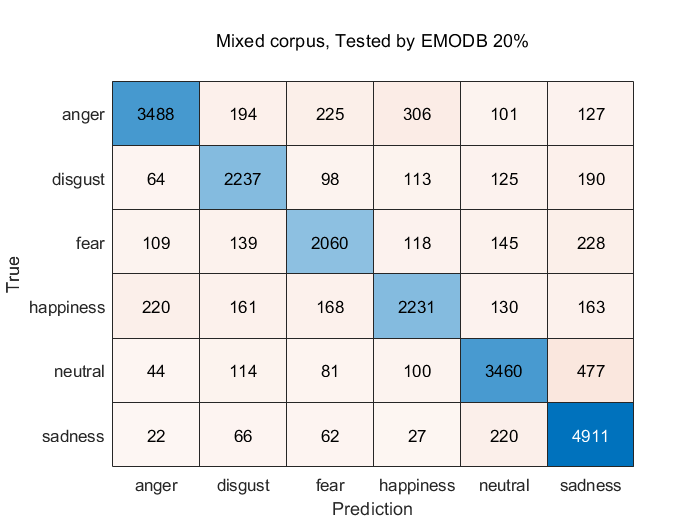


[validationPredictions, validationScores] = predict(mdl_mixedcorpus, validationPredictors);

correctPredictions = (validationPredictions == validationResponse);
isMissing = ismissing(validationResponse);
correctPredictions = correctPredictions(~isMissing);
validationAccuracy = sum(correctPredictions)/length(correctPredictions);

figure(1);
confusion_matrix1 = confusionchart(validationResponse,validationPredictions);
confusion_matrix1.Title = {'';'Mixed corpus, Tested by EMODB 20%';''};
confusion_matrix1.YLabel = 'True';
confusion_matrix1.XLabel = 'Prediction';

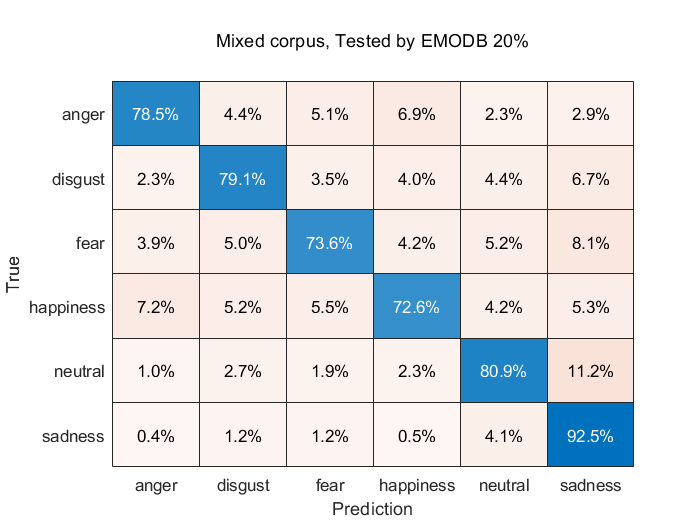


figure(2);
confusion_matrix2 = confusionchart(validationResponse,validationPredictions);
confusion_matrix2.Title = {'';'Mixed corpus, Tested by EMODB 20%';''};
confusion_matrix2.YLabel = 'True';
confusion_matrix2.XLabel = 'Prediction';
% confusion_matrix2.RowSummary = 'row-normalized';
confusion_matrix2.Normalization = 'row-normalized';